# Análise de Filtro Discreto

## Preparando o Ambiente

clear all;
close all;
Nfig = 1; % Contador de Figuras

## Resposta ao Impulso

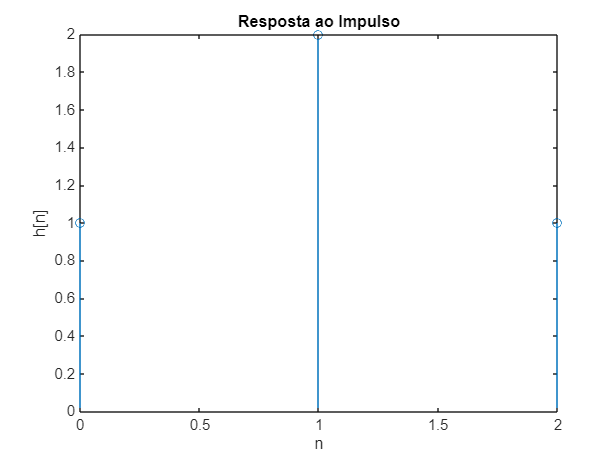

h = [1 2 1]; % Resposta do filtro ao impulso
n = 0:length(h)-1; % Contador de amostras
figure(Nfig)
Nfig = Nfig+1; % Incrementa o contador de figuras
stem(n, h) % Visualizar a resposta ao impulso
title("Resposta ao Impulso");
ylabel("h[n]");
xlabel("n");

## Resposta a uma Entrada Qualquer

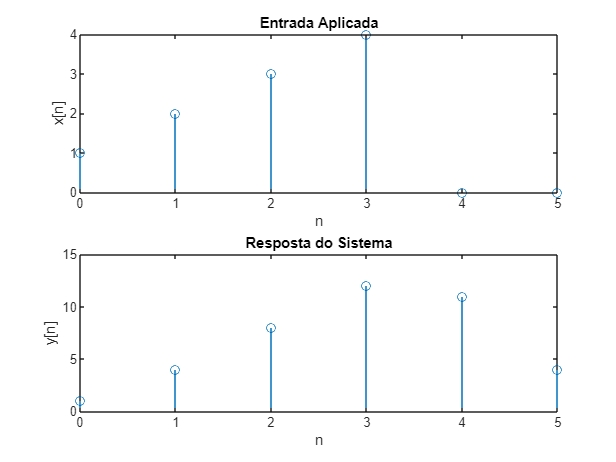

x = [1 2 3 4]; % Entrada
y = conv(h, x); % Resposta do sistema a entrada x
n = 0:length(y)-1; % Contador de amostras
figure(Nfig)
Nfig = Nfig+1; % Incrementa o contador de figuras
subplot(2, 1, 1); % Subplot 2 linhas, 1 coluna, 1° janela
stem(n, [x zeros(1, length(y) - length(x))]) % Entrada
title("Entrada Aplicada");
ylabel("x[n]");
xlabel("n");
subplot(2, 1, 2); % Subplot 2 linhas, 1 coluna, 2° janela
stem(n, y) % Visualizar a resposta ao impulso
title("Resposta do Sistema");
ylabel("y[n]");
xlabel("n");

% Observe que o tamanho(resposta) = tamanho(entrada) + tamanho(resposta ao impulso)
length(y) % Tamanho da resposta

ans = 6

length(x)+length(h) % Tamanho(entrada) + tamanho(resposta ao impulso)

ans = 7

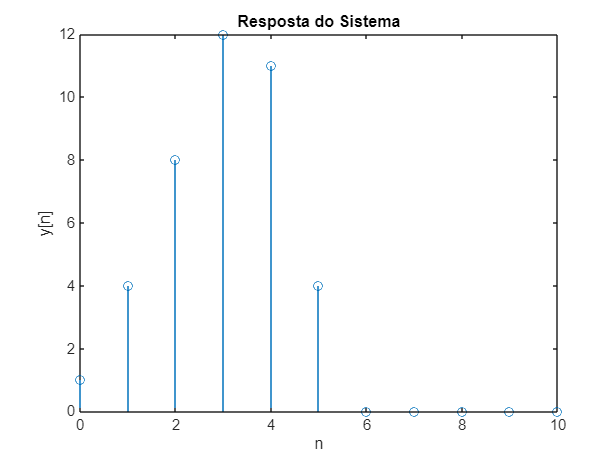

% Perceba tambem que após a última amostra plotada, a resposta é nula,
% ou seja, y[n] = 0 para n >= N(x) + N(h) - 1 (lembrando que a contagem
% começa em zero)
% Apenas para título de visualização, poltemos a resposta com mais pontos
y = [y zeros(1,5)]; % Adiciona mais pontos para respostas (nulos)
n = 0:length(y)-1; % Contador de amostras
figure(Nfig); % Figura Nfig
Nfig = Nfig+1; % Incrementa o contador de figuras
stem(n, y)
title("Resposta do Sistema");
ylabel("y[n]");
xlabel("n");

## Transformada Z

Hz = tf(h, 1, -1,'Variable','z^-1') % Transformada Z

Hz =
 
  1 + 2 z^-1 + z^-2
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties


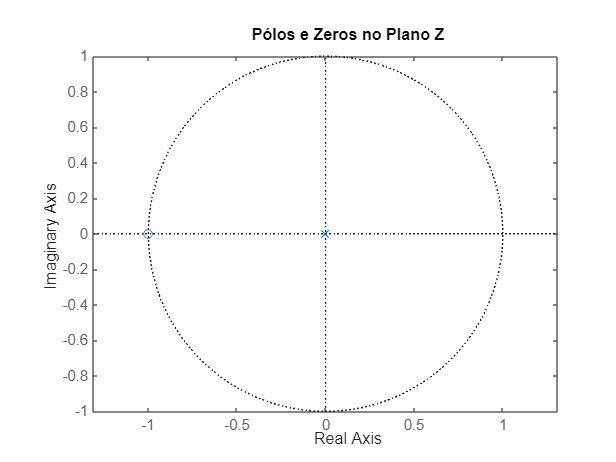

figure(Nfig); % Figura Nfig
Nfig = Nfig+1; % Incrementa o contador de figuras
pzmap(Hz); % Plota os pólos e zeros
title("Pólos e Zeros no Plano Z");
axis('equal'); % Não distoce a figura

% Repare que os pólos estão contidos no círculo de raio unitário,
% logo, o sistema é estável
% Outra maneira de comprovar a estabilidade é verificando que 
% o somatório dos coeficientes de h[n] é finito

## Resposta em Frequência

num = fliplr(h); % Coeficientes do numerador de H(z)
den = [1 zeros(1, length(h)-1)]; % Coeficientes do numerador de H(z)
Hz = tf(num, den, -1) % H(z)

Hz =
 
  z^2 + 2 z + 1
  -------------
       z^2
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties


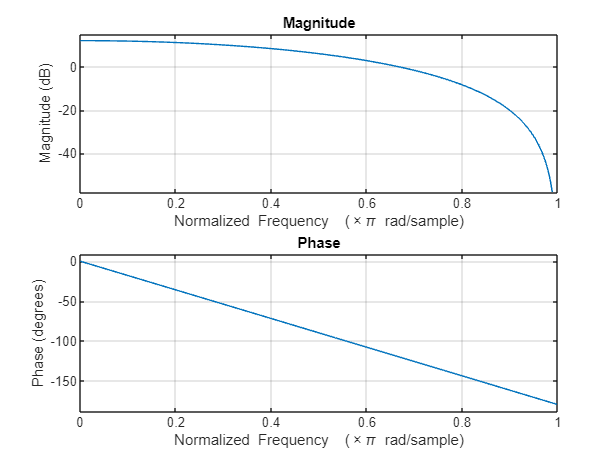

figure(Nfig); % Figura Nfig
Nfig = Nfig+1; % Incrementa o contador de figuras 
freqz(num, den); % Plota a resposta em frequência